Drag plot 

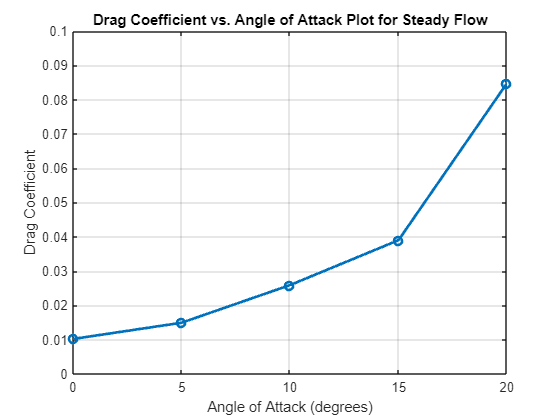

% Data
angle_of_attack = [0 5 10 15 20];  % Angle of Attack in degrees
drag_coefficient = [0.010213656 0.014943427 0.02592154 0.039009861 0.084790794];  % Drag Coefficient

% Create the plot
figure;
plot(angle_of_attack, drag_coefficient, '-o', 'LineWidth', 2);
xlabel('Angle of Attack (degrees)');
ylabel('Drag Coefficient');
title('Drag Coefficient vs. Angle of Attack Plot for Steady Flow');
grid on;

% Customize the appearance (optional)
xlim([0 20]);  % Set x-axis limits
ylim([0 0.1]);  % Set y-axis limits

Lift plot 

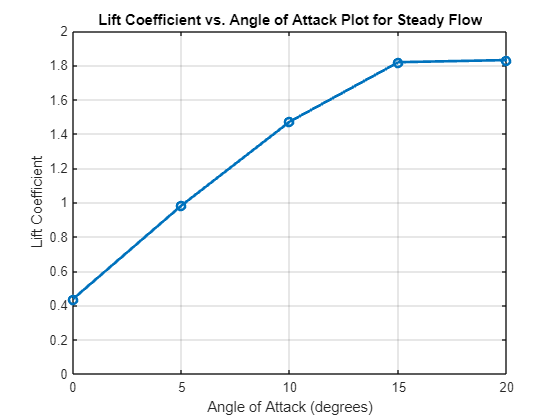

% Data for Lift Coefficient vs. Angle of Attack
angle_of_attack = [0 5 10 15 20];  % Angle of Attack in degrees
lift_coefficient = [0.43723958 0.98251979 1.472477 1.8181889 1.8305779];  % Lift Coefficient

% Create the plot
figure;
plot(angle_of_attack, lift_coefficient, '-o', 'LineWidth', 2);
xlabel('Angle of Attack (degrees)');
ylabel('Lift Coefficient');
title('Lift Coefficient vs. Angle of Attack Plot for Steady Flow');
grid on;

% Customize the appearance (optional)
xlim([0 20]);  % Set x-axis limits
ylim([0 2]);  % Set y-axis limits

Cl/Cd Plot (Dividing)

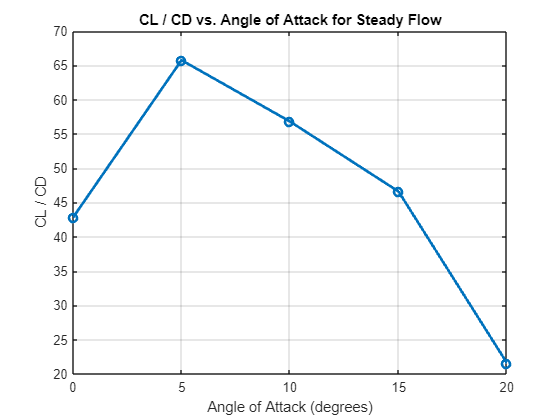

% Data for Angle of Attack, Drag Coefficient, and Lift Coefficient
angle_of_attack = [0 5 10 15 20];  % Angle of Attack in degrees
drag_coefficient = [0.010213656 0.014943427 0.02592154 0.039009861 0.084790794];  % Drag Coefficient
lift_coefficient = [0.43723958 0.98251979 1.472477 1.8181889 1.8305779];  % Lift Coefficient

% Calculate CL / CD
cl_cd = lift_coefficient ./ drag_coefficient;

% Create the plot
figure;
plot(angle_of_attack, cl_cd, '-o', 'LineWidth', 2);
xlabel('Angle of Attack (degrees)');
ylabel('CL / CD');
title('CL / CD vs. Angle of Attack for Steady Flow');
grid on;

% Customize the appearance
xlim([0 20]);  % Set x-axis limits

Cl/Cd Plot (And)

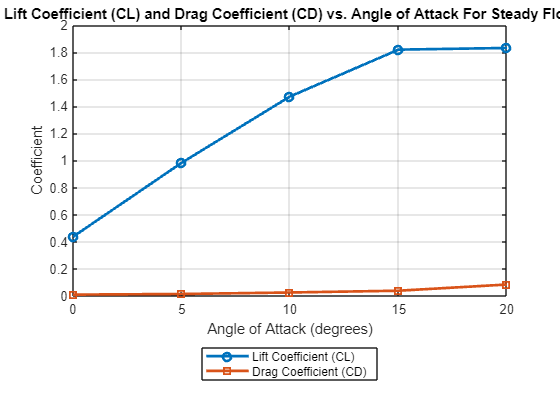

% Data for Angle of Attack, Drag Coefficient, and Lift Coefficient
angle_of_attack = [0 5 10 15 20];  % Angle of Attack in degrees
drag_coefficient = [0.010213656 0.014943427 0.02592154 0.039009861 0.084790794];  % Drag Coefficient
lift_coefficient = [0.43723958 0.98251979 1.472477 1.8181889 1.8305779];  % Lift Coefficient

% Create the plot
figure;
plot(angle_of_attack, lift_coefficient, '-o', 'LineWidth', 2, 'DisplayName', 'Lift Coefficient (CL)');
hold on;
plot(angle_of_attack, drag_coefficient, '-s', 'LineWidth', 2, 'DisplayName', 'Drag Coefficient (CD)');
hold off;

% Add labels, title, and legend
xlabel('Angle of Attack (degrees)');
ylabel('Coefficient');
title('Lift Coefficient (CL) and Drag Coefficient (CD) vs. Angle of Attack For Steady Flow');
legend('Location', 'southoutside');
grid on;

% Customize the appearance
xlim([0 20]);  % Set x-axis limits

Pressure Difference plot 

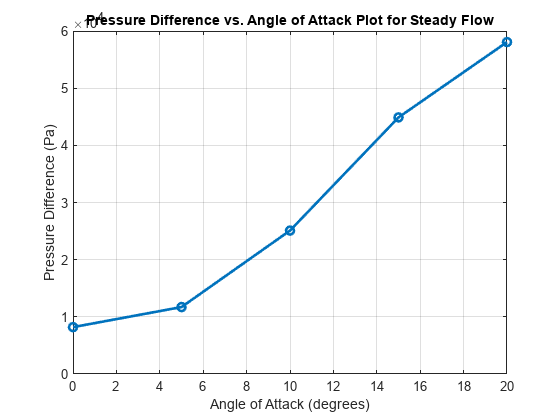

% Data for Pressure Difference vs. Angle of Attack
pressure_difference = [8198.22 11708.66 25089.67 44884.12 58065.71];  % Pressure Difference in Pascals

% Create the plot
figure;
plot(angle_of_attack, pressure_difference, '-o', 'LineWidth', 2);
xlabel('Angle of Attack (degrees)');
ylabel('Pressure Difference (Pa)');
title('Pressure Difference vs. Angle of Attack Plot for Steady Flow');
grid on;

% Customize the appearance (optional)
xlim([0 20]);  % Set x-axis limits

drag-co/lift-co plot 

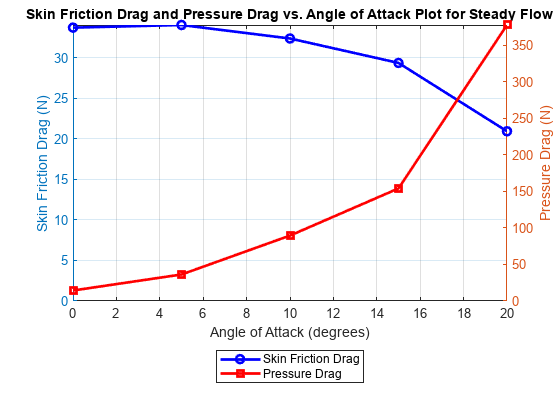

% Data for Pressure Drag and Skin Friction Drag
angle_of_attack = [0 5 10 15 20];  % Angle of Attack in degrees
pressure_drag = [14.37445 36.303181 89.617405 154.20662 378.02033];  % Pressure Drag
skin_friction_drag = [33.679789 34.004163 32.340872 29.330905 20.91195];  % Skin Friction Drag

% Create the plot
figure;

% Plot Skin Friction Drag on the primary y-axis
yyaxis left;
plot(angle_of_attack, skin_friction_drag, '-o', 'LineWidth', 2, 'Color', 'b');
ylabel('Skin Friction Drag (N)');
ylim([0 max(skin_friction_drag)]);  % Scale primary y-axis from 0 to max value

% Plot Pressure Drag on the secondary y-axis
yyaxis right;
plot(angle_of_attack, pressure_drag, '-s', 'LineWidth', 2, 'Color', 'r');
ylabel('Pressure Drag (N)');
ylim([0 max(pressure_drag)]);  % Scale secondary y-axis from 0 to max value

% Add labels and title
xlabel('Angle of Attack (degrees)');
title('Skin Friction Drag and Pressure Drag vs. Angle of Attack Plot for Steady Flow');
grid on;

% Add legend
legend('Skin Friction Drag', 'Pressure Drag', 'Location', 'southoutside');

% Approximate intersection
hold on;

% Finding intersection (optional, just visual)
intersection_x = interp1(pressure_drag - skin_friction_drag, angle_of_attack, 0);
fprintf('The approximate intersection occurs at an angle of attack of %.2f degrees.\n', intersection_x);

The approximate intersection occurs at an angle of attack of 4.47 degrees.
